# **Problem 2**

In this problem we are tasked with designing a BME classifier for 3 sets of input data using their ML estimates of unknown mean and unknown covariance multivariate normal distributions. In order to do so we will use the ML estimates for unknown parameter multivariate normal distributions formulations proven in the textbook as follows:


$$\hat{\;\mu_i } =\frac{1}{n_i }\sum_{k=1}^{n_i } x_k \;,\hat{\;\Sigma_i } =\frac{1}{n_i }\sum_{k=1}^{n_i } \left(x_k -\hat{\mu_i } \right){\left(x_k -\hat{\mu_i } \right)}^T \;$$


Where$\;1\le i\le c\;$, $c$ is the number of classes and $n_i$ is the number of samples drawn from that class.

We will then use $g_i \left(x\right)=\ln \left(P\left(\omega_i |x\right)\right)=\ln \left(p\left(x|\omega_i \right)\frac{P\left(\omega_i \right)}{p\left(x\right)}\right)$. Since all the classes are presumed to be equiprobable (equal priors or $P\left(\omega_i \right)$s) and $p\left(x\right)$is the same across all $g_i \left(x\right)$s, the equation above simplifies to $g_i \left(x\right)=\ln \left(p\left(x|\omega_i \right)\right)$. We will use this discriminiant function to determine which class every sample belongs to.

**Analysis of the Iris Data (a):**

First we will read the data set from file and store it into a variable:

clearvars
X_Iris = load("Data/Iris-Data_dat.txt");

Now we will perform the leave-one-out method on 'X_Iris':

preds = zeros([size(X_Iris, 1), 1]);
g = zeros([size(X_Iris, 1), 3]);
for i=1:size(X_Iris, 1)
    % extract one as test and leave the rest as training data
    X_test = X_Iris(i,:);
    X_test_var = X_test(:,2:end);
    X_test_label = X_test(:, 1);
    X_train = X_Iris([1:i-1, i+1:end],:);
    % isolate each class from the training data and separate the variables.
    c1 = X_train(X_train(:,1) == 1, :);
    c1_vars = c1(:,2:end);
    c2 = X_train(X_train(:,1) == 2, :);
    c2_vars = c2(:,2:end);
    c3 = X_train(X_train(:,1) == 3, :);
    c3_vars = c3(:,2:end);
    % then calculate mean and covariance for each class
    % cov(x, 1) provides biased estimates.
    mu1 = mean(c1_vars);
    S1 = cov(c1_vars,1);
    mu2 = mean(c2_vars);
    S2 = cov(c2_vars,1);
    mu3 = mean(c3_vars);
    S3 = cov(c3_vars,1);
    % display the specifications of the first classifier
    if i == 1
        disp('Specifications of the first classifier: ');
        mu1
        S1
        mu2
        S2
        mu3
        S3
    end
    % discriminant function values
    g(i, 1) = log(mvnpdf(X_test_var, mu1, S1));
    g(i, 2) = log(mvnpdf(X_test_var, mu2, S2));
    g(i, 3) = log(mvnpdf(X_test_var, mu3, S3));
    % argmax
    [~, preds(i)] = max(g(i,:));
end

Specifications of the first classifier: 


mu1 =    50.0408   34.2653   14.6327    2.4694


S1 =    12.4065    9.9075    1.6476    1.0421
    9.9075   14.3582    1.1791    0.9367
    1.6476    1.1791    3.0079    0.6010
    1.0421    0.9367    0.6010    1.1062


mu2 =    59.3600   27.7000   42.6000   13.2600


S2 =    26.1104    8.3480   17.9240    5.4664
    8.3480    9.6500    8.1000    4.0380
   17.9240    8.1000   21.6400    7.1640
    5.4664    4.0380    7.1640    3.8324


mu3 =    65.8800   29.7400   55.5200   20.2600


S3 =    39.6256    9.1888   29.7224    4.8112
    9.1888   10.1924    6.9952    4.6676
   29.7224    6.9952   29.8496    4.7848
    4.8112    4.6676    4.7848    7.3924


We can now evaluate the method.

First we will print out the information for all of the misclassified samples:

error_idx = find(preds ~= X_Iris(:,1));
disp('Erroneous predictions:');

Erroneous predictions:


for i=1:length(error_idx)
    val = error_idx(i);
    fprintf(['\tSample No.: %d\n' ...
        '\tActual Class: %d\n' ...
        '\tPredicted Class: %d\n' ...
        '\tg%d(x): %f\n' ...
        '\tg%d(x): %f\n\n'], val, X_Iris(val,1), preds(val),...
        X_Iris(val,1), g(val, X_Iris(val, 1)),...
        preds(val), g(val, preds(val))); 
end

	Sample No.: 69
	Actual Class: 2
	Predicted Class: 3
	g2(x): -16.086159
	g3(x): -15.261056

	Sample No.: 71
	Actual Class: 2
	Predicted Class: 3
	g2(x): -12.739603
	g3(x): -11.037519

	Sample No.: 84
	Actual Class: 2
	Predicted Class: 3
	g2(x): -12.421013
	g3(x): -9.780056

	Sample No.: 134
	Actual Class: 3
	Predicted Class: 2
	g3(x): -10.825058
	g2(x): -10.153224



As we can see, the misclassified samples are extremely close to the decision boundary where $g_i \left(x\right)=g_j \left(x\right)$and the classifier is prone to error. 

Then we will draw up the confusion matrix to visually assess how well the Classifier has performed.

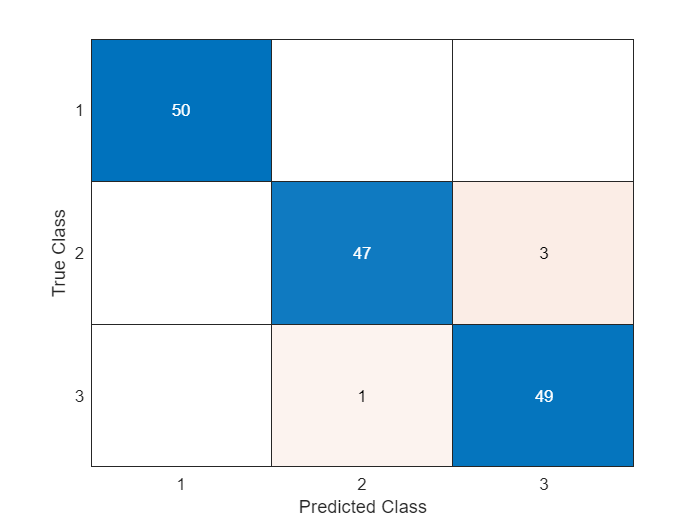

cc = confusionchart(X_Iris(:,1), preds);

Finally we will display error rates per class:

e = zeros([3, 1]);
for i=1:3
    e(i) = 100*(1 - cc.NormalizedValues(i,i)/sum(cc.NormalizedValues(i,:)));
end
fprintf(['Class Error Percentages:\n' ...
    '\tClass 1: %f\n' ...
    '\tClass 2: %f\n' ...
    '\tClass 3: %f\n'], e(1), e(2), e(3));

Class Error Percentages:
	Class 1: 0.000000
	Class 2: 6.000000
	Class 3: 2.000000


Samples from the first class have been perfectly classified while combined total of 4 errors can be seen across classes 2 and 3. This can probably be attributed to the fact that the mean of the first class is further away from classes 2 and 3 than classes 2 and 3 are from each other. Meaning that it is easier to isolate samples generated from class 1 while the neighbourhood of the decision boundary $g_2 \left(x\right)=g_{3\;} \left(x\right)$houses more data from classes 2 and 3 and therefore is more prone to error.

**Analysis of the Liquid Database (b)**

Everything is the same as section (a). Therefore we will refrain from repeating the explainations and display only the results.

clearvars
X_Liquid_DB = load("Data/Liquid-Data_dat.txt");
preds = zeros([size(X_Liquid_DB, 1), 1]);
g = zeros([size(X_Liquid_DB, 1), 3]);
for i=1:size(X_Liquid_DB, 1)
    % extract one as test and leave the rest as training data
    X_test = X_Liquid_DB(i,:);
    X_test_var = X_test(:,2:end);
    X_test_label = X_test(:, 1);
    X_train = X_Liquid_DB([1:i-1, i+1:end],:);
    % isolate each class from the training data and separate the variables. 
    c1 = X_train(X_train(:,1) == 1, :);
    c1_vars = c1(:,2:end);
    c2 = X_train(X_train(:,1) == 2, :);
    c2_vars = c2(:,2:end);
    c3 = X_train(X_train(:,1) == 3, :);
    c3_vars = c3(:,2:end);
    % then calculate mean and covariance for each class
    % cov(x, 1) provides biased estimates.
    mu1 = mean(c1_vars);
    S1 = cov(c1_vars,1);
    mu2 = mean(c2_vars);
    S2 = cov(c2_vars,1);
    mu3 = mean(c3_vars);
    S3 = cov(c3_vars,1);
    % display the specifications of the first classifier
    if i == 1
        disp('Specifications of the first classifier: ');
        mu1
        S1
        mu2
        S2
        mu3
        S3
    end
    % discriminant function values
    g(i, 1) = log(mvnpdf(X_test_var, mu1, S1));
    g(i, 2) = log(mvnpdf(X_test_var, mu2, S2));
    g(i, 3) = log(mvnpdf(X_test_var, mu3, S3));
    % argmax
    [~, preds(i)] = max(g(i,:));
end

Specifications of the first classifier: 


mu1 = 	1.0e+03 *

    1.3736    0.2456    0.2981    0.5526    0.1062    1.1166


S1 = 	1.0e+04 *

    0.2094   -0.0154    0.0756    0.2327    0.0045    0.3735
   -0.0154    0.0516   -0.0063   -0.0349    0.0063   -0.0151
    0.0756   -0.0063    0.1579    0.3649    0.0004    0.3357
    0.2327   -0.0349    0.3649    1.5338    0.0041    1.6164
    0.0045    0.0063    0.0004    0.0041    0.0136    0.0910
    0.3735   -0.0151    0.3357    1.6164    0.0910    4.9026


mu2 = 	1.0e+03 *

    1.2279    0.2245    0.2081    0.3087    0.1056    0.5195


S2 = 	1.0e+04 *

    0.2853   -0.0359   -0.0143    0.1324   -0.0002    0.0360
   -0.0359    0.0981    0.0691    0.0173   -0.0020    0.0205
   -0.0143    0.0691    0.4910    0.2436   -0.0042   -0.1341
    0.1324    0.0173    0.2436    0.8434   -0.0048    0.1468
   -0.0002   -0.0020   -0.0042   -0.0048    0.0406    0.0362
    0.0360    0.0205   -0.1341    0.1468    0.0362    2.4367


mu3 = 	1.0e+03 *

    1.3154    0.2437    0.0781    0.7396    0.0683    0.6299


S3 = 	1.0e+04 *

    0.2753    0.0235    0.0116    0.4204   -0.0020   -0.0532
    0.0235    0.0334    0.0147    0.0523    0.0037   -0.0307
    0.0116    0.0147    0.0843    0.2437   -0.0096   -0.0815
    0.4204    0.0523    0.2437    5.2292   -0.1472    0.3136
   -0.0020    0.0037   -0.0096   -0.1472    0.0128    0.0003
   -0.0532   -0.0307   -0.0815    0.3136    0.0003    1.2971


error_idx = find(preds ~= X_Liquid_DB(:,1));
disp('Erroneous predictions:');

Erroneous predictions:


for i=1:length(error_idx)
    val = error_idx(i);
    fprintf(['\tSample No.: %d\n' ...
        '\tActual Class: %d\n' ...
        '\tPredicted Class: %d\n' ...
        '\tg%d(x): %f\n' ...
        '\tg%d(x): %f\n\n'], val, X_Liquid_DB(val,1), preds(val),...
        X_Liquid_DB(val,1), g(val, X_Liquid_DB(val, 1)),...
        preds(val), g(val, preds(val))); 
end

	Sample No.: 74
	Actual Class: 2
	Predicted Class: 1
	g2(x): -39.649437
	g1(x): -34.466431

	Sample No.: 131
	Actual Class: 3
	Predicted Class: 2
	g3(x): -33.895322
	g2(x): -33.328143



Both misclassifications have extremely close $g\left(x\right)$ values as expected. Again, confirming that the area around the decision boundary is most prone to classification errors.

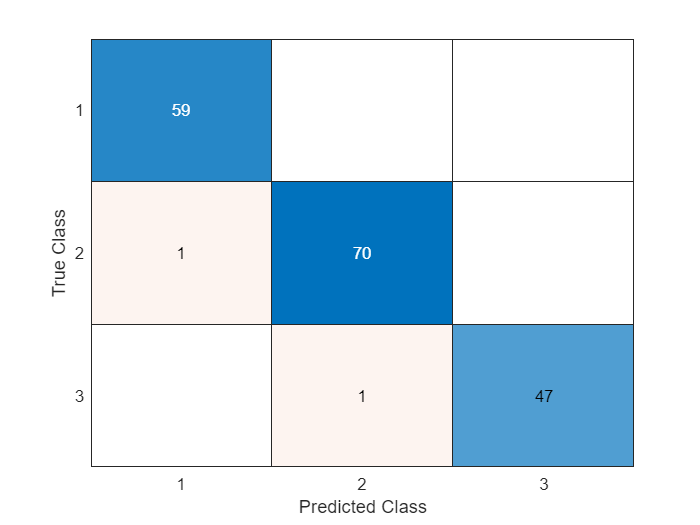

cc = confusionchart(X_Liquid_DB(:,1), preds);

e = zeros([3, 1]);
for i=1:3
    e(i) = 100*(1 - cc.NormalizedValues(i,i)/sum(cc.NormalizedValues(i,:)));
end
fprintf(['Class Error Percentages:\n' ...
    '\tClass 1: %f\n' ...
    '\tClass 2: %f\n' ...
    '\tClass 3: %f\n'], e(1), e(2), e(3));

Class Error Percentages:
	Class 1: 0.000000
	Class 2: 1.408451
	Class 3: 2.083333


Only 2 classification errors implying that the distributions had little to no overlap. 

**Analysis of the Normal Data (c)**

First we will read in the train and test data:

clearvars
mu1_actual = [0; 0];
mu2_actual = [4; 0];
Sigma = [2, 0; 0, 2];
X_train = load("Data/Normal-Data-Training_dat.txt");
X_test = load("Data/Normal-Data-Testing_dat.txt");

Extract labels and variables:

X_train_vars = X_train(:, 2:end);
X_train_labels = X_train(:, 1);
X_test_vars = X_test(:, 2:end);
X_test_labels = X_test(:, 1);

Now we will use ML estimates for each class in the train variables:

c1 = X_train(X_train(:, 1) == 1, :);
c1_vars = c1(:, 2:end);
c2 = X_train(X_train(:, 1) == 2, :);
c2_vars = c2(:, 2:end);
mu1 = mean(c1_vars);
S1 = cov(c1_vars, 1);
mu2 = mean(c2_vars);
S2 = cov(c2_vars, 1);

We can see how close our estimates are to the actual values by measuring their MSEs.

Estimates vs. Actuals:

mse_mu1 = mean((mu1 - mu1_actual').^2, "all")

mse_mu1 = 0.0068

mse_mu2 = mean((mu2 - mu2_actual').^2, "all")

mse_mu2 = 1.8118e-04

mse_Sigma1 = mean((S1 - Sigma).^2, "all")

mse_Sigma1 = 0.0039

mse_Sigma2 = mean((S2 - Sigma).^2, "all")

mse_Sigma2 = 0.0052

As we can see, all of the MSEs are close to 0, indicating a highly accurate estimate of variables.

And finally we will test these estimates on our test variables:

g = zeros([size(X_test, 1), 2]);
g(:, 1) = log(mvnpdf(X_test_vars, mu1, S1));
g(:, 2) = log(mvnpdf(X_test_vars, mu2, S2));
[~, preds] = max(g,[],2);

Evaluation:

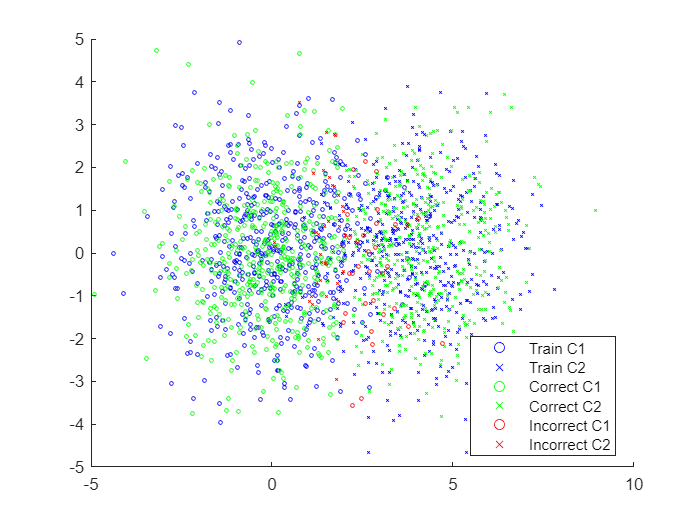

% seperate correct/incorrect classifications by class and plot everything
% on the same figure
bad_c1 = X_test_vars((preds ~= X_test_labels & X_test_labels == 1), :);
bad_c2 = X_test_vars((preds ~= X_test_labels & X_test_labels == 2), :);
good_c1 = X_test_vars((preds == X_test_labels & X_test_labels == 1), :);
good_c2 = X_test_vars((preds == X_test_labels & X_test_labels == 2), :);
scatter(c1_vars(:,1), c1_vars(:,2), 5,'blue', 'o');
hold on
scatter(c2_vars(:,1), c2_vars(:,2), 5,'blue', 'x'); 
hold on
scatter(good_c1(:,1), good_c1(:,2), 5,'green', 'o');
hold on
scatter(good_c2(:,1), good_c2(:,2), 5,'green', 'x');
hold on
scatter(bad_c1(:,1), bad_c1(:,2), 5,'red', 'o');
hold on
scatter(bad_c2(:,1), bad_c2(:,2), 5,'red', 'x');
legend('Train C1', 'Train C2', ...
    'Correct C1', 'Correct C2', ...
    'Incorrect C1', 'Incorrect C2', ...
    'location', 'best');
hold off

As we can see, most of the errors seem to be happening around the area where the spans of the two distributions clash, around the decision boundary which is the most error prone area.

We can list all of the misclassified samples along with their $g\left(x\right)$ values:

error_idx = find(preds ~= X_test_labels);
fprintf('Total number of misclassifications: %d', length(error_idx));

Total number of misclassifications: 67

for i=1:length(error_idx)
    val = error_idx(i);
    fprintf(['\tSample No.: %d\n' ...
        '\tActual Class: %d\n' ...
        '\tPredicted Class: %d\n' ...
        '\tg%d(x): %f\n' ...
        '\tg%d(x): %f\n\n'], val, X_test(val,1), preds(val),...
        X_test(val,1), g(val, X_test(val, 1)),...
        preds(val), g(val, preds(val))); 
end

	Sample No.: 16
	Actual Class: 1
	Predicted Class: 2
	g1(x): -9.094795
	g2(x): -3.689358

	Sample No.: 25
	Actual Class: 1
	Predicted Class: 2
	g1(x): -4.250662
	g2(x): -4.245139

	Sample No.: 37
	Actual Class: 1
	Predicted Class: 2
	g1(x): -6.050886
	g2(x): -2.671231

	Sample No.: 66
	Actual Class: 1
	Predicted Class: 2
	g1(x): -5.425858
	g2(x): -3.249382

	Sample No.: 94
	Actual Class: 1
	Predicted Class: 2
	g1(x): -4.905303
	g2(x): -2.830241

	Sample No.: 98
	Actual Class: 1
	Predicted Class: 2
	g1(x): -3.859494
	g2(x): -3.408686

	Sample No.: 120
	Actual Class: 1
	Predicted Class: 2
	g1(x): -4.297148
	g2(x): -2.998807

	Sample No.: 133
	Actual Class: 1
	Predicted Class: 2
	g1(x): -5.171974
	g2(x): -4.133515

	Sample No.: 134
	Actual Class: 1
	Predicted Class: 2
	g1(x): -4.586158
	g2(x): -4.220740

	Sample No.: 148
	Actual Class: 1
	Predicted Class: 2
	g1(x): -4.839040
	g2(x): -3.193404

	Sample No.: 151
	Actual Class: 1
	Predicted Class: 2
	g1(x): -4.132709
	g2(x): -4.015052

	Samp

Below we can see the confusion matrix on the test data to assess how the classifier has performed visually. We can observe that the errors are almost equally distributed between the two classes which stems from the fact that both of the classes share the same covariance matrix:

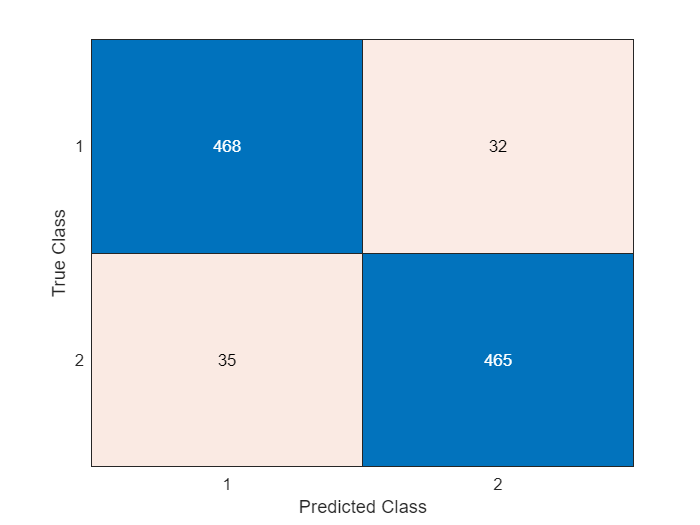

cc = confusionchart(X_test_labels, preds);

We can now calculate the empirical error rates per class, and overall:

e = zeros([2, 1]);
for i=1:size(e, 1)
    e(i) = 100*(1 - cc.NormalizedValues(i,i)/sum(cc.NormalizedValues(i,:)));
end
e_overall = 100*(1 - sum(diag(cc.NormalizedValues))/sum(cc.NormalizedValues, "all"));
fprintf(['Empirical Error Percentages:\n' ...
    '\tClass 1: %f\n' ...
    '\tClass 2: %f\n' ...
    '\tOverall: %f\n'], e(1), e(2), e_overall);

Empirical Error Percentages:
	Class 1: 6.400000
	Class 2: 7.000000
	Overall: 6.700000


In order to calculate the theoretical error rates we will use the actual $\mu \;$and $\Sigma \;$of the two distributions. We will also use the result of problem 2.9 which states that in a two equiprobable class classification problem, where the feature vectors in each class are normally distributed with covariance matrix $\Sigma \;$and corresponding mean vectors $\mu_1$ and $\mu_2$, the BME classifier results in a theoretical error probabilty given by:


$$P_B =\int_{\frac{d_m }{2}}^{+\infty } \frac{1}{\sqrt{2\pi \;}}e^{\left(-\frac{z^2 }{2}\right)} d\;z\;$$


Where $d_m$ is the Mahalanobis distance between the mean vectors.

First we will calculate $d_m$:

d_m = sqrt((mu1_actual - mu2_actual)'*inv(Sigma)*(mu1_actual - mu2_actual));

And then we will plug this value into the formula above to calculate the theoretical error rate:

expr = @(z) (1/sqrt(2*pi)).*exp(-(z.^2)./2);
P_B = integral(expr, 0.5*d_m, inf);
fprintf('Theoretical Overall Error: %f\nEmpirical Overall Error: %f', 100*P_B, e_overall);

Theoretical Overall Error: 7.864960
Empirical Overall Error: 6.700000

We can see that these errors differ only in about 1% and are indeed very close to one another, implying that the classifer was trained on a reasonably general dataset.